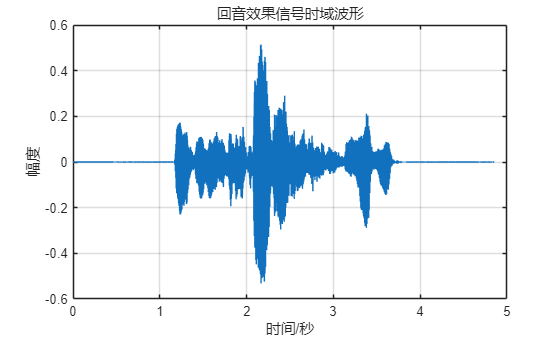

%% 要求：
% 简易回音效果，要求n_delay≥10000个采样点。
% 绘制出回音效果音频信号的时域波形。

clear; clc;
[y, Fs] = audioread('dspx1.wav');
n = length(y);
x = (0:n-1)/Fs; 

n_delay = 10000;  % 延迟点数
alpha = 0.5;      % 回音衰减系数

y_delay = zeros(n, 1);
% 将原始信号的前n-n_delay个样本复制到延迟信号的第(n_delay+1)个位置开始的地方
y_delay(n_delay+1:n) = y(1:n-n_delay);
y_echo = y + alpha * y_delay;

figure;
% subplot(2,1,1); % 时域图
plot(x, y_echo);
xlabel('时间/秒');
ylabel('幅度');
title('回音效果信号时域波形');
grid on;

% Y_echo = fft(y_echo, n);
% f = (0:n-1)*Fs/n;
% subplot(2,1,2);
% plot(f(1:n/2), abs(Y_echo(1:n/2))/max(abs(Y_echo(1:n/2))));
% xlabel('频率/Hz');
% ylabel('归一化幅度');
% title('回音效果信号频谱');
% axis([0, 8000, 0, 1]);
% grid on;

% sound(y_echo, Fs);